# **利用 MATLAB 中特殊函数指令，绘制特殊函数**

**        本节涉及到的特殊函数有：贝塞尔函数、勒让德多项式、球函数。**

## 1.贝塞尔函数

**        贝塞尔函数、诺依曼函数、虚宗量贝塞尔函数和虚宗量汉克尔函数等，它们被冠之以“特殊函数”。但特殊函数并不“特殊”。事实上，在很多语言如 MATLAB里面上述特殊函数都是内置的函数，可以直接调用。绘制*****n*****阶贝塞尔函数曲线，**$J_n \left(x\right)$

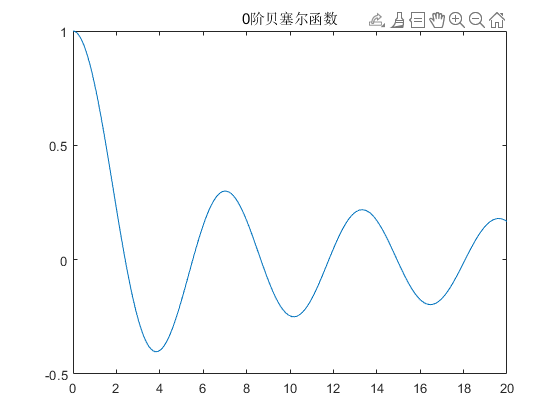

x=0:0.1:20;    	%定义自变量取值范围
n=0;%定义阶数
y=besselj(n,x); 	%计算n阶贝塞尔函数的函数值
figure
plot(x,y);         	%绘图
title([num2str(n),'阶贝塞尔函数']);
set(gcf,'Visible','on');   	    %强制图片弹出显示

**        绘制n阶诺依曼函数曲线，**$N_n \left(x\right)$

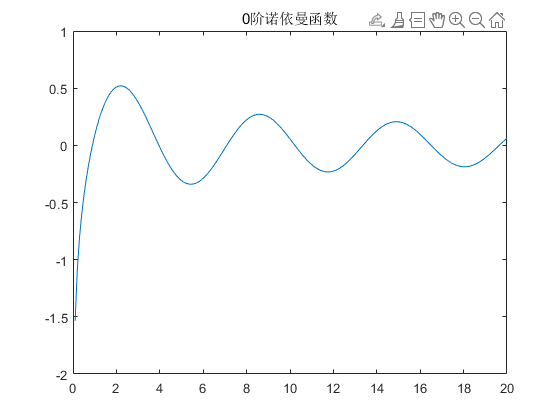

x=0:0.1:20;    	%定义自变量取值范围
n=0;%定义阶数
y=bessely(n,x); 	%计算n阶诺依曼函数的函数值
figure
plot(x,y);          	%绘图
title([num2str(n),'阶诺依曼函数']);
set(gcf,'Visible','on');   	    %强制图片弹出显示

**        绘制n阶虚宗量贝塞尔函数曲线，**$I_n \left(x\right)$

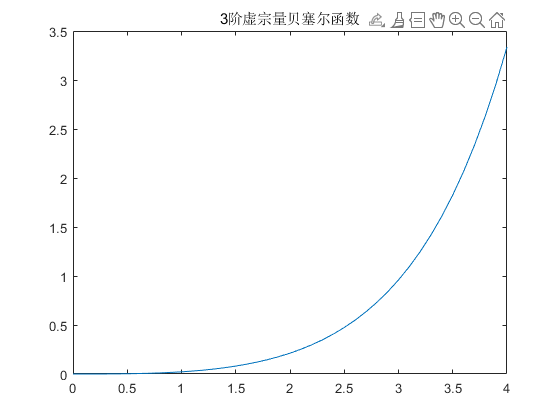

x=0:0.1:4;     	%定义自变量取值范围
n=3;%定义阶数
y=besseli(n,x);  	%计算n阶虚宗量贝塞尔函数的函数值
figure
plot(x,y);           	%绘图
title([num2str(n),'阶虚宗量贝塞尔函数']);
set(gcf,'Visible','on');   	    %强制图片弹出显示

**        绘制3阶虚宗量汉克尔函数曲线，**$K_n \left(x\right)$

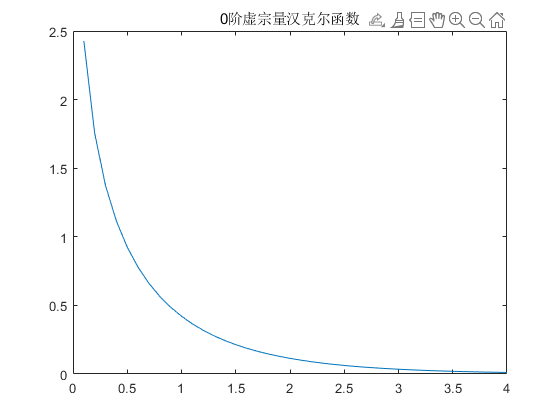

x=0:0.1:4;     	%定义自变量取值范围
n=0;%定义阶数
y=besselk(n,x);  	%计算n阶虚宗量汉克尔函数的函数值
figure
plot(x,y);            	%绘图
title([num2str(n),'阶虚宗量汉克尔函数']);
set(gcf,'Visible','on');   	    %强制图片弹出显示

## 2.勒让德多项式

**        有了前面的贝塞尔函数等做基础，现在讨论一下勒让德多项式的情况。和熟悉的正离余弦函数一样，勒让德多项式、连带勒让德多项式等也不是什么“特殊”的函数。在很多应用软件如 MATLAB 环境下,勒让德多项式等是作为内置函数出现的，可以直按使用。MATLAB可以一次计算所有的连带勒让德多项式。可以根据需要自行选择，如下面示例的就是计算**$P_n$**的情况。**

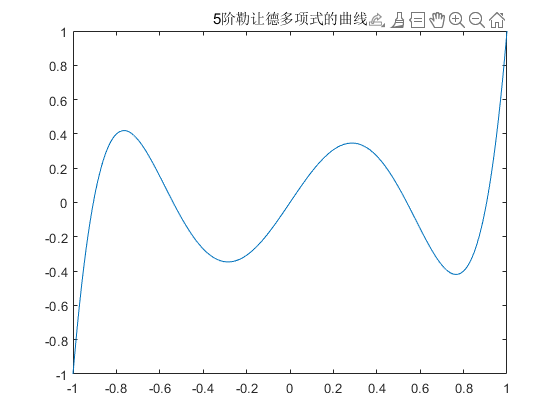

x=-1:0.01:1;       		%x取值范围
m = 0;       
n =5;                  
y=legendre(n,x);    		%计算所有的n阶连带勒让德多项式
y=y(m+1,:);          		
figure
plot(x,y); 
title([num2str(n),'阶勒让德多项式的曲线']); 
set(gcf,'Visible','on');   	    %强制图片弹出显示

**       如果要选择**$P_n^m$，**则如下：**

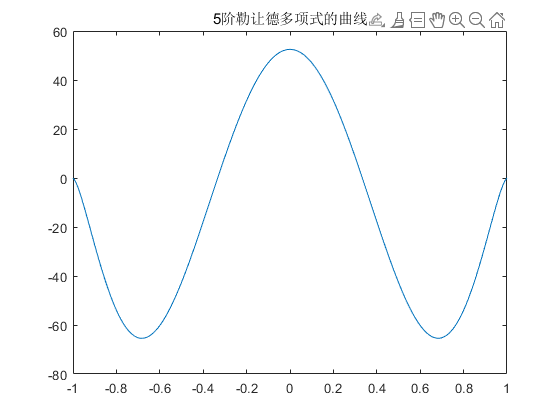

m =3;       
n =5;                    
y=legendre(n,x); 		%计算所有的n阶连带勒让德多项式
y=y(m+1,:);       		
figure
plot(x,y);         		%绘制曲线
title('5阶勒让德多项式的曲线');
set(gcf,'Visible','on');   	    %强制图片弹出显示

## 3.球函数：用MATLAB绘制比较典型的球函数

        **也可以用 MATLAB绘制比较典型的球函数，具体代码如下。在本程序中，以半径**$r_0$**的球面为参考，将所绘球函数先做归一化处理，再调整为幅度为 amp 的二元函数，并相对于参考球面绘制出来。**

**参考球面半径：**

r0 =6;                           

**球函数的最大幅度：**

amp=2.7;                           

**设置次数n及阶数m：**

n=6;                             	
m=2;                   

**生成角度网格数据**：

theta=linspace(0,pi,40);              	%在仰角方向选择40个点
phi=linspace(0,2*pi,50);             	%在水平方位角方向选择50个点
[phi,theta]=meshgrid(phi,theta);       	%生成网格数据，并存储在phi和theta两个矩阵中

 **计算球面函数值**：

Ymn=legendre(n,cos(theta(:,1)));      	%计算Pnm(cos(theta))，注意包含了所有阶数
Ymn=Ymn(m+1,:)';                 	%选取m阶的数据，保存再Ymn列向量中

**延拓球面函数值**：

yy=Ymn;                         	%以下操作，将Ymn延拓为形如theta矩阵的形式
for lp=2: size(theta,2)
    yy=[yy Ymn];
end

**计算曲面坐标**：

yy=yy.*sin(m*phi);      				%或者yy = yy.*cos(order*phi)  计算球函数值
mag=max(max(abs(yy)));          		%取最大值以便归一化
rho=r0+amp*yy/mag;             		%归一化，并计算函数值距离球形的长度
r=rho.*sin(theta);                 
x=r.*cos(phi);                   		%曲面x坐标
y=r.*sin(phi);                    		%曲面y坐标

**绘制曲面**：

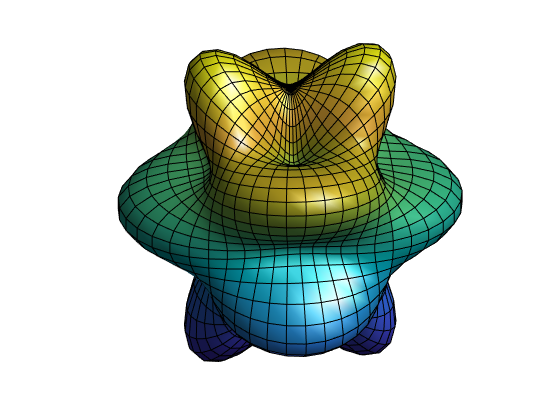

figure
z=rho.*cos(theta);                		%曲面z坐标
surf(x,y,z)                      		%绘制曲面
light                           		%以下用于修饰曲面，可以忽略
lighting phong                  		%设置光照模式为phong
axis equal off                   		%x、y等比例显示，关闭坐标轴
view(40,30);                    	 	%视角
camzoom(1.5)                   		%相机拉近，放大
set(gcf,'Visible','on');   	    %强制图片弹出显示